# Reproducing arXiv Experiment

## Channel Parameters

clear
K = 8; % # of channel pairs
D = 4; % System dimensions
h = 6.626e-34; % Planck's constant

% Each channel has an initial state rho_k
psi_m = [0;1;-1;0]./sqrt(2); % EPR state vector |HV> - |VH>
rho_psi_m = psi_m*psi_m'; % construct density matrix for initial entangled states
rho_K = repmat(rho_psi_m, 1, 1, K); % initial channel states are all |HV>-|VH>

% Each channel has unitary describing change in quantum states after
% transmission. U_K(:,:,k) returns the unitary of the kth channel pair
U_K = repmat(eye(D),[1,1,K]); % Ideal case where channel unitaries are identities

% Define spectrum partitioning; central stop band assumed
wss_f0_hz = 192.3125e12; % WSS center frequency
chan_width_hz = 25e9;
wss_Pin_W = 15.6e-3*1e-8*0.7378*1e-1; % biphoton beam power into WSS
spect_fwhm_hz = 310e9; % power spectrum FWHM
power_spect = sqrSincPowerSpect(wss_f0_hz, spect_fwhm_hz, wss_Pin_W); % obtain function handle to gaussian power spectrum

## Calculating channel fluxes

% Each channel has associated photon flux which can be calculated from
% input power spectrum and spectrum partitioning

% Matrices of channel boundaries
lo_freq_bounds = zeros(K,2); % freq bounds of lower spectral slices
hi_freq_bounds = zeros(K,2); % freq bounds of upper spectral slices

for k = 1:K
        lo_freq_bounds(k,:) = sort([wss_f0_hz - chan_width_hz*(k+1/2), wss_f0_hz - chan_width_hz*(k-1/2)]);
        hi_freq_bounds(k,:) = sort([wss_f0_hz + chan_width_hz*(k-1/2), wss_f0_hz + chan_width_hz*(k+1/2)]);
end


chan_fluxes = zeros(K, 1);
for k = 1:K
    chan_fluxes(k) = 1/h*integral(@(x) power_spect(x)./x, lo_freq_bounds(k,1), lo_freq_bounds(k,2));
    chan_fluxes(k) = chan_fluxes(k) + ...
                     1/h*integral(@(x) power_spect(x)./x, hi_freq_bounds(k,1), hi_freq_bounds(k,2));
    chan_fluxes(k) = chan_fluxes(k)/2;
end
preset_chan_fluxes = [3.896850301648412e+06
                      3.764082137963968e+06
                      3.764082137963968e+06
                      3.764082137963968e+06
                      3.764082137963968e+06
                      3.764082137963968e+06
                      3.764082137963968e+06
                      1.742115013711593e+07];
% chan_fluxes = preset_chan_fluxes;

## Constructing allocation matrix from allocation vector

alloc1 = [1;3;3;3;3;3;3;2];
alloc2 = [3;3;1;2;0;0;0;0];

alloc_vect = uint8(alloc1);
% disp(alloc_vect)

## Constructing QLAN object

q = QLAN([], 'arxiv_users.json'); % fully connected network of arXiv users
q.coinc_wind_s = 10e-9;

q.configChans(chan_fluxes, U_K, rho_K);

## Evaluating allocation

metrics = q.evalAlloc(alloc_vect, rho_psi_m);
q.R_N

ans = 	1.0e+05 *

    0.6457
    0.1555
    1.0689


F_L = metrics(:,1)

F_L =     0.6539
    0.4664
    0.6896


ebr_L = metrics(:,2)

ebr_L =    67.3776
         0
  149.0406


## Plot Power Spectrum 

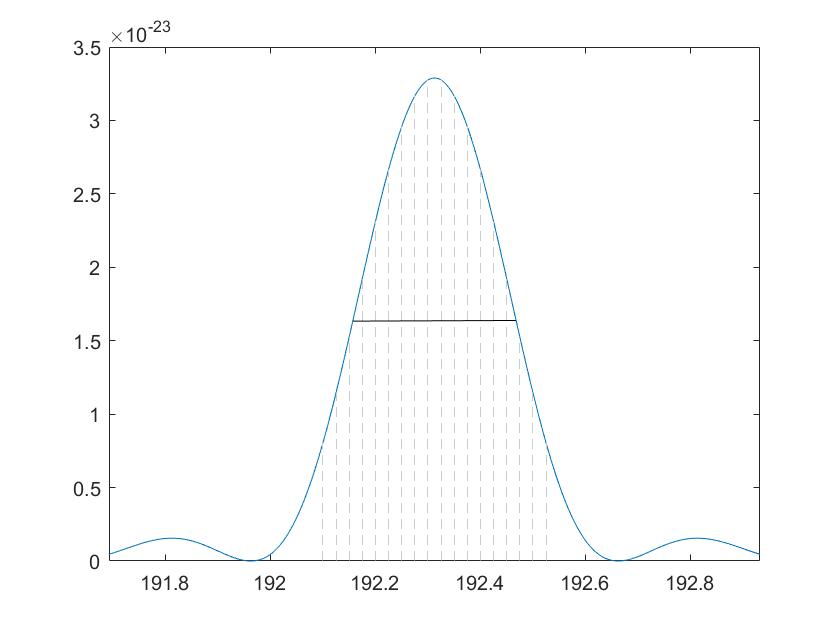

scale = 1e12; % plot axis in THz
chan_freqs = unique([lo_freq_bounds(:); hi_freq_bounds(:)]); % spectral slice boundary frequencies

% generate plot domain and add frequency points of interest
spect_freqs = linspace(0.9*min(lo_freq_bounds,[],'all'), 1.1*max(hi_freq_bounds, [], 'all'), 10000);
spect_freqs = unique([spect_freqs wss_f0_hz lo_freq_bounds(:)' hi_freq_bounds(:)']);

% Evaluate spectrum
full_spect = power_spect(spect_freqs);

% Plotting spectrum
spect_fig = figure();
plot(spect_freqs./scale, full_spect)
xlim([wss_f0_hz-2*spect_fwhm_hz, wss_f0_hz + 2*spect_fwhm_hz]/scale)

hold on

% Plotting spectral slice boundaries
stem(chan_freqs./scale, power_spect(chan_freqs), 'Color', [0.8 0.8 0.8], 'LineStyle', '--', 'MarkerSize', 0.0001)

% Plotting FWHM line
half_max = max(full_spect)/2;
fwhm_inds = find(abs(full_spect - half_max) < eps(half_max)*1e14);
fwhm_freqs_hz = [wss_f0_hz-spect_fwhm_hz/2 wss_f0_hz+spect_fwhm_hz/2];
plot(fwhm_freqs_hz/scale, full_spect(fwhm_inds([1,end])), 'k-')

## Plot Channel Flux Plot

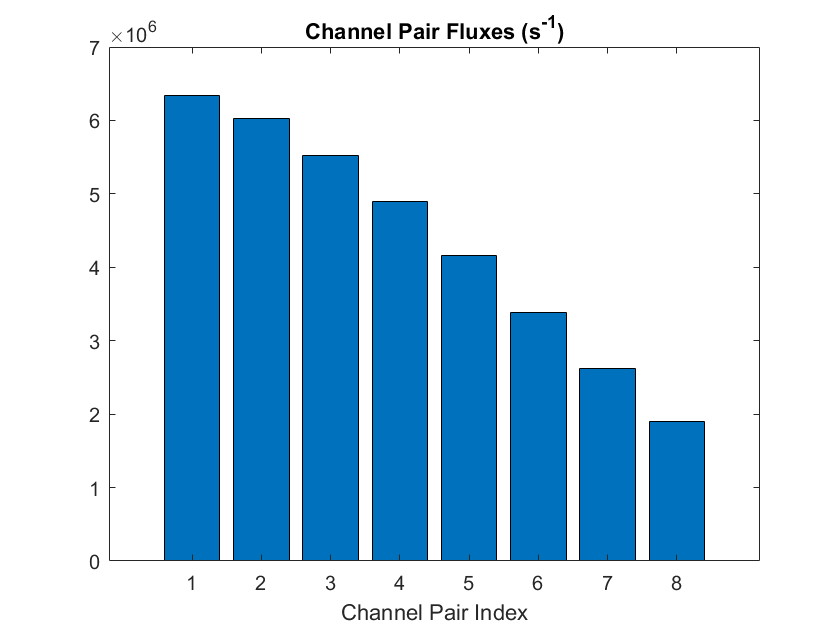

chan_flux_fig = figure();
bar(chan_fluxes)
title("Channel Pair Fluxes (s^{-1})")
xlabel("Channel Pair Index")

## Plot Link Fluxes

link_flux_fig = figure();
bar(categorical(link_names), link_fluxes(2:end))

Unrecognized function or variable 'link_names'.

title("Link fluxes (s^{-1})")

## Plot User fluxes

user_flux_fig = figure();
bar(categorical(user_names), user_fluxes)
title("User Fluxes (s^{-1})")

## Plot User singles count rates

user_RN_fig = figure();
bar(categorical(user_names), R_N)
title("User Singles Rates (cps)")

## Plot Link Coincidence rates

link_coinc_fig = figure();
subplot(2,1,1)
bar(categorical(link_names),A_L)
title("Link Accidental Coincedence Rate (s^{-1})")
subplot(2,1,2)
bar(categorical(link_names),C_L)
title("Link True Coincedence Rate (s^{-1})")

## Plotting fidelity and ebit rate

ebit_fig = figure();
bar(categorical(link_names), ebit_rate);  
title("Link ebit rates")
disp(F_L)